ASD = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/ASD_w_longitudinalv1_thresholded.mat');
tensor_ASD = ASD.tensor_ASDv1;
NT = load('/Users/domo/Documents/MATLAB/Graph_theory/Dissertation_code/Thresholding/NT_w_longitudinalv1_thresholded.mat');
tensor_NT = NT.tensor_NTv1;

ASD_w = tensor_ASD(:,:,:,71);
NT_w = tensor_NT(:,:,:,71);

%spot check
nnz(ASD_w(:,:,24))/(96^2)

ans = 0.3000

nnz(NT_w(:,:,17))/(96^2)

ans = 0.3000


sum(diag(NT_w(:,:,3)))

ans = 0

sum(diag(ASD_w(:,:,19)))

ans = 0

ASD = [10001, 10002, 10003, 10004, 10005, 10008, 10010, 10020, 10021, 10050, 10059, 10061, 10069, 10077, 10079, 10090, 10091, 10092, 10093, 10096,...
    10101, 10115, 10119, 10124, 11001, 11003, 11007, 11014, 11019, 11031, 11038, 11044, 11054, 11059, 11061];
NT = [10009, 10013, 10014, 10015, 10016, 10017, 10019, 10036, 10044, 10052, 10057, 10076, 10086, 10088, 10103, 10106, 10112, 10113, 11006,...
    11008, 11009, 11013, 11016, 11021, 11027, 11028, 11032, 11039, 11041, 11074];

RM96 = readtable('/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx');

mod_NT = [];
cs_NT = [];

% beta1s_filt_NT = [];
% NT_filt = []; 
for i = 1:length(NT)
    % if ismember(NT(i),beta1s_NT(:,1))
        % ind = find(NT(i)==beta1s_NT(:,1));
        % NT_filt = [NT_filt; NT(i)];
        % beta1s_filt_NT = [beta1s_filt_NT; beta1s_NT(ind,:)];

        w = NT_w(:,:,i);
        [m,Q] = modularity_und(w);
        mod_NT = [mod_NT, Q];
        cs_NT = [cs_NT, m];
    % end
end


mod_ASD = [];
cs_ASD = [];

% beta1s_filt_ASD = [];
% ASD_filt = [];

for i = 1:length(ASD)
    % if ismember(ASD(i),beta1s_ASD(:,1))
    %     ind = find(ASD(i)==beta1s_ASD(:,1));
    %     ASD_filt = [ASD_filt; ASD(i)];
    %     beta1s_filt_ASD = [beta1s_filt_ASD; beta1s_ASD(ind,:)];

        w = ASD_w(:,:,i);
        [m,Q] = modularity_und(w);
        mod_ASD = [mod_ASD, Q];
        cs_ASD = [cs_ASD, m];
    % end
end

%difference in modularity score ebtween ASD and NT
[p_m, od_m, es_m] = permutationTest(mod_ASD,mod_NT,10000)

p_m = 0.1437

od_m = 0.0055

es_m = 0.3660

%permutation testing to compare community structure between groups
[viASD, miASD] = partition_distance(cs_ASD);
[viNT, miNT] = partition_distance(cs_NT);
within_ASD = mean(miASD,'all');
within_NT = mean(miNT,'all');
tot_mni = within_ASD+within_NT;
% mi_od = mean(miASD,'all')-mean(miNT,'all');
randomdifferences = zeros(1,10000);
for i = 1:10000
    allobservations = [cs_ASD,cs_NT];
    permtuation = randperm(size(allobservations,2));
    randSample1 = allobservations(:,permtuation(1:size(cs_ASD,2)));
    randSample2 = allobservations(:,permtuation(size(cs_ASD,2)+1:length(permtuation)));
    [viS1, miS1] = partition_distance(randSample1);
    [viS2, miS2] = partition_distance(randSample2);
    randomdifferences(i) = mean(miS1,'all')+mean(miS2,'all');
end
p = (length(find(abs(randomdifferences)>abs(tot_mni)))+1)/(10000+1)

p = 0.0519

%visualizing differences in community assignment 



%difference in assignment of different nodes
p_nodes = zeros(96,1);
nASD_sm = zeros(96,96);
nNT_sm = zeros(96,96);
for i = 1:96
    bin_ASD = zeros(96,size(cs_ASD,2));
    bin_NT = zeros(96,size(cs_NT,2));
    for j = 1:size(cs_ASD,2)
        label = cs_ASD(i,j);
        bin_ASD(:,j) = cs_ASD(:,j)==label;
        nASD_sm(i,:) = nASD_sm(i,:)+bin_ASD(:,j)';
    end
    for k = 1:size(cs_NT,2)
        label = cs_NT(i,k);
        bin_NT(:,k) = cs_NT(:,k)==label;
        nNT_sm(i,:) = nNT_sm(i,:)+bin_NT(:,k)';
    end
    R_ASD = corrcoef(bin_ASD);
    R_NT = corrcoef(bin_NT);
    R_od = mean(R_ASD,'all')+mean(R_NT,'all');
    randomdifferences = zeros(1,10000);
    for l = 1:10000
        allobservations = [bin_ASD,bin_NT];
        permtuation = randperm(size(allobservations,2));
        randSample1 = allobservations(:,permtuation(1:size(cs_ASD,2)));
        randSample2 = allobservations(:,permtuation(size(cs_ASD,2)+1:length(permtuation)));
        R_S1 = corrcoef(randSample1);
        R_S2 = corrcoef(randSample2);
        randomdifferences(l) = mean(R_S1,'all')+mean(R_S2,'all');
    end
    p_nodes(i,1) = (length(find(abs(randomdifferences)>abs(R_od)))+1)/(10000+1);
end

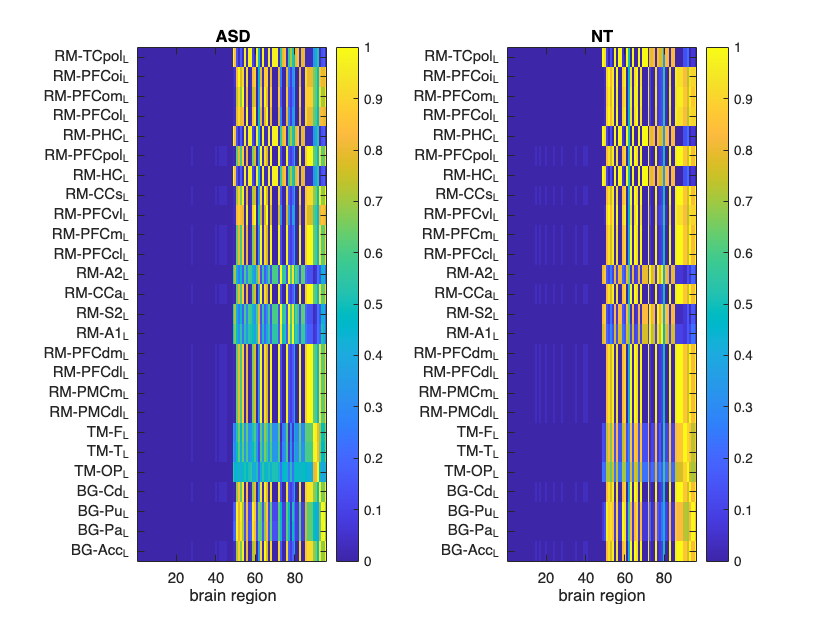

sig_nASD = [];
sig_nNT = [];
tick_labels = [];
for i = 1:96
    if p_nodes(i,1)<0.05
        sig_nASD = [sig_nASD; nASD_sm(i,:)];
        sig_nNT = [sig_nNT; nNT_sm(i,:)];
        tick_labels = [tick_labels; RM96{i,'Labels'}];
    end
end



figure;
subplot(1,2,1)
imagesc(sig_nASD/35)
title('ASD')
xlabel('brain region')
yticks([1:length(p_nodes<0.05)])
yticklabels(tick_labels)
colorbar
subplot(1,2,2)
imagesc(sig_nNT/30)
yticks([1:length(p_nodes<0.05)])
yticklabels(tick_labels)
xlabel('brain region')
title('NT')
colorbar

RM96 = readtable("/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx");

for i = 1:96
    if p_nodes(i,1)<0.05
        disp(RM96{i,"Labels"})
        disp(p_nodes(i))
    end
end

    {'RM-TCpol_L'}



    0.0285



    {'RM-PFCoi_L'}



    0.0471



    {'RM-PFCom_L'}



    0.0432



    {'RM-PFCol_L'}



    0.0338



    {'RM-PHC_L'}



    0.0261



    {'RM-PFCpol_L'}



    0.0163



    {'RM-HC_L'}



    0.0253



    {'RM-CCs_L'}



    0.0358



    {'RM-PFCvl_L'}



    0.0147



    {'RM-PFCm_L'}



    0.0131



    {'RM-PFCcl_L'}



    0.0135



    {'RM-A2_L'}



    0.0217



    {'RM-CCa_L'}



    0.0118



    {'RM-S2_L'}



    0.0059



    {'RM-A1_L'}



    0.0168



    {'RM-PFCdm_L'}



    0.0142



    {'RM-PFCdl_L'}



    0.0128



    {'RM-PMCm_L'}



    0.0135



    {'RM-PMCdl_L'}



    0.0172



    {'TM-F_L'}



    0.0294



    {'TM-T_L'}



    0.0143



    {'TM-OP_L'}



    0.0083



    {'BG-Cd_L'}



    0.0425



    {'BG-Pu_L'}



    0.0415



    {'BG-Pa_L'}



    0.0411



    {'BG-Acc_L'}



    0.0342



struct_Newman_table = readtable("/Users/domo/Documents/MATLAB/Data/RM96_labels.xlsx");
struct_Newman_table.P_value = p_nodes

struct_Newman_table = 96×2 table
        Labels         P_value
    _______________    _______

    {'RM-TCpol_R' }    0.83182
    {'RM-TCs_R'   }    0.78302
    {'RM-Amyg_R'  }     0.9735
    {'RM-PFCoi_R' }     0.9692
    {'RM-IA_R'    }    0.43036
    {'RM-PFCom_R' }    0.78912
    {'RM-TCc_R'   }    0.60614
    {'RM-PFCol_R' }     0.9676
    {'RM-TCi_R'   }    0.61084
    {'RM-PHC_R'   }    0.82892
    {'MM82a-G_R'  }    0.65043
    {'RM-PMCvl_R' }    0.82262
    {'RM-VACv_R'  }    0.50765
    {'RM-Ip_R'    }    0.57354
    {'RM-PFCpol_R'}    0.70543
    {'RM-HC_R'    }    0.83722


writetable(struct_Newman_table,'struct_Newman_nodal_results.xlsx')